# Demo 02: 3D ME Phantom data

## data download and setup

add paths and set up data paths. Download phantom data (1.82 GB "phantom-DMI.tar.gz")  from [zenodo.org (DOI: 10.5281/zenodo.14652737)](https://doi.org/10.5281/zenodo.14652737).

% add all dependencies
addpath(genpath('/ptmp/pvalsala/Packages/mapVBVD'))
addpath(genpath('/ptmp/pvalsala/Packages/DeuteMetCon'))


% data path
sn='/ptmp/pvalsala/deuterium/dataForPublication/phantom-DMI';
dirst_me=dir(fullfile(sn,"*trufi_5E*.dat"));
dirst_noise=dir(fullfile(sn,"*trufi*noise*.dat"));




## load metabolite structure 

The chemical shifts, measured relaxation times and labels of all four metabolites in phantom is organised in a array of struct

% second argument is the frequency offset of water in Hz
metabolites=getMetaboliteStruct('phantom',0);


## `Inputs and flags for metabolite mapping`

`All functions and data required for all data processing steps like image reconstruciton, coil combination and spectral seperation were encapsualted in a single class `MetCon_CSI.m`. All inputs and flags except the raw data file is a name-value pair as described below.`

% | name                        | description                                                | default   | possible options                                                 |
% |-----------------------------|------------------------------------------------------------|-----------|------------------------------------------------------------------|
% | metabolites                 | struct array with definition of metabolites                | []        | see getMetaboliteStruct.m function                               |
% | fm                          | 1H fieldmap in rad/s                                       | []        | 3D numeric matrix or 'IDEAL'                                     |
% | csm                         | coil maps                                                  | []        | 3D numeric matrix                                                |
% | mask                        | mask for spectral separation                               | []        | 3D logical matrix , scalar percentile (1-100) threshold          |
% | doDenosing                  | SVD denoising                                              | 0         | scalar No of components, -1 for debug                            |
% | Solver                      | spectral separation method                                 | 'IDEAL'   | {'phaseonly','pinv','IDEAL','IDEAL-modes','AMARES','LorentzFit'} |
% |                             |                                                            |           | 'phaseonly'- linear method with only phase evolution             |
% |                             |                                                            |           | 'pinv'- linear method with full signal model                     |
% |                             |                                                            |           | 'IDEAL'- iterative IDEAL algorithm                               |
% |                             |                                                            |           | 'IDEAL-modes'-IDEAL algorithm for phase cycled data              |
% |                             |                                                            |           | 'AMARES'- AMARES spectral fitting                                |
% |                             |                                                            |           | 'LorentzFit'- lorentzian spectral fitting                        |
% | parfor                      | flag to use parfor                                         | true      | boolean                                                          |
% | doZeroPad                   | zero pad factor                                            | [1 1 1 0] | positive scalar array [3 physical axis x 1 time]                 |
% | 'doSmoothFM','maxit'        | IDEAL flags: fieldmap smooth factor and maximum iterations | 1,10      | scalar(+ve: gaussian, -ve: median),postive scalar                |
% | doPhaseCorr                 | phase correction mode                                      | 'none'    | {'none','Manual','Burg'}                                         |
% | 'CoilSel','PCSel','EchoSel' | arrays to picks some of coils, time points and phasecyles. | 1:max()   | positive integer array                                           |
% | doNoiseDecorr               | flag to perform noise decorrelation                        | true      | boolean                                                          |

### `Get noise decoorelation matrix `

`trufi sequence acquire noise data only when parallel imaging is enabled. Therefore, we acquire noise scan with 0 flip angle seperately.`

twix_noise=mapVBVD(fullfile(sn,dirst_noise(1).name),'rmos');

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:


    40.4 MB read in    8 s


[D_noise,D_image,noise_info]=CalcNoiseDecorrMat(twix_noise);
%D_image is the noise correlation from image data measured with 0 FA

### `assemble inputs and processing flags`

ME_setting={'NoiseDecorr',D_image,'mask',[],'metabolites',metabolites,...
            'doPhaseCorr',true,'doZeropad',[1 1 1]*0.5,'parfor',true,'fm','IDEAL','Solver','pinv'};
%
%'fm','IDEAL' : estimate field map from the averaged phasecycle volume using IDEAL algorithm
% 'Solver','pinv' : linear fit (least square fit of full signal model)

## Process data

ME_filename=fullfile(sn,dirst_me(end).name);
mcobj_me=MetCon_ME(ME_filename,ME_setting{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   856.4 MB read in    8 s
starting reco
estimating field map(1/2) 
Starting parallel pool (parpool) using the 'Processes' profile ...


Connected to parallel pool with 36 workers.
estimating metabolities(2/2) 
reco  time =   65.2 s
Calculating bSSFP profile basis
done.....

 Metabolite fitting done in 5.2 s ! 
Performed pixel shift along read: (0.0,-2.2,-5.2 ,-7.2) mm
Metabolite mapping time =    5.3 s


### Plotting

After image reconstruciton and spectral seperation, metbolite amplitudes are store in mcobj_csi.Metcon. The 4D Metcon matrix and 2H field map estimated by IDEAL algorithm can be quickly visualized with `PlotResults` method.

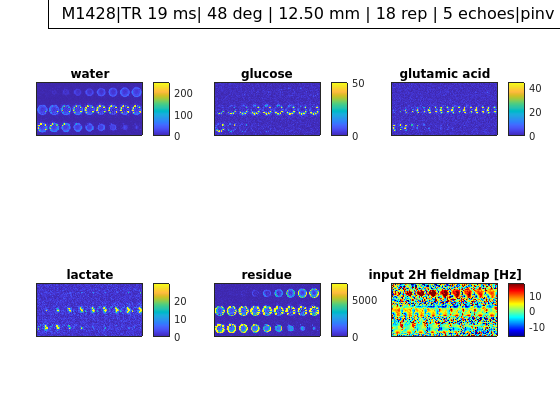

mcobj_me.PlotResults()

## Data structure of Metcon_ME object

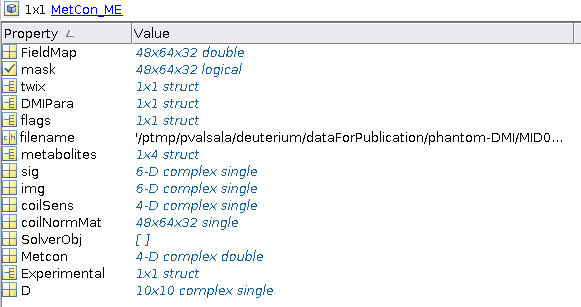

 Where 

- DMIPara are the important sequence parameters parsed from twix with `getDMIPara.m` fucntion

- flags contains all the processing flags

- sig - averaged signal [CHA x LIN  x COL x PAR x ECO x REP]

- img - reconstructed image [CHA x Phase x Read xSlice x echo x PC]

- Metcon - Metabolite amplitudes [CHA x 3 physical dimension x time]

- Experimental- contains all experimental outputs of processing (fieldmap, residue, other fit parameters, fit quality)

- D- noise decorrelation matrix.

## Other miscallaneous methods which can be useful

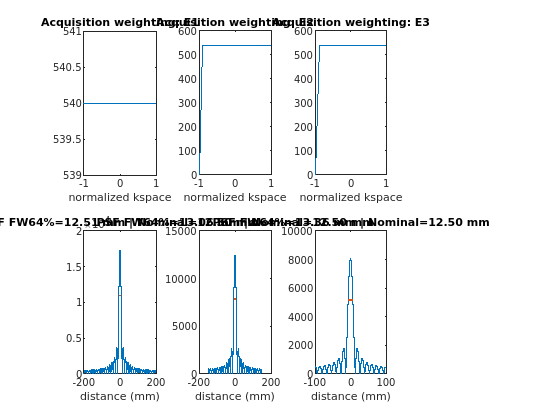

voxel_size_mm =    12.5122
   13.0642
   13.3602
         0


% The metabolite amplitudes can be normalized into SNR 
metcon_SNR= mcobj_me.getNormalized();

% method and quantified into mM with 10 mM water reference using `getmM`
% fucntion. 
metcon_mM= mcobj_me.getmM();

% caculate measurement time after glucose intake in mins
Intake_time_mins=mcobj_me.getMinutesAfterIntake('08:00');

% export NIFTI volumes of all outputs (average image, metabolite amplitude in SNR unit and mM)
pn=fullfile(sn,'proc',sprintf('ME_%s',datetime('today','Format','yyyyMMMdd')));
mkdir(pn);
niiFileName=mcobj_me.WriteImages(pn);

%plot the k-space weighting and PSF to get realistic voxel size (FW64%)
voxel_size_mm= getPSF_CSI(mcobj_me.twix)

### Debug (only for 'pinv' (linear) fit mode)

Useful for checking data at a particular voxel index. [24,33,27] is a lactate voxel.

   12.4828
    1.6200
    0.1262
   77.7509



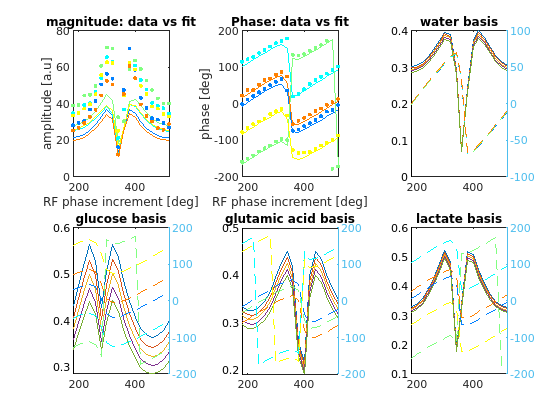

%prints metabolite amplitudes and plot fit and basis functions
mcobj_me.demoFit([24,33,27])